
%#ok<*CLALL>

clear all;clc 

A = [zeros(2) eye(2); zeros(2) zeros(2)]; 
B = [zeros(2); eye(2)]; 

% Constraint vector conventions: low; high; ...

% Input constraint, acceleration. 
e = [-1; 1; -1; 1]; 

% Position constraints. 
positionBounds = [-1; 1; -1; 1]*50; 

% Velocity constraints. 
velocityBounds = [-1; 1; -1; 1]*10; 

% TPBVP test. 
tspan = 0 : 1E-2 : 5; 

chaserInitialStates = [1; 1; 0; 0]; 
evaderPosition = [2; 2]; 

% Initial guess
% guess = zeros(8, length(tspan));
% guess(1,:) = linspace(chaserInitialStates(1), evaderPosition(1), length(tspan)); % Linear guess for x
% guess(2,:) = linspace(chaserInitialStates(2), evaderPosition(2), length(tspan)); % Linear guess for y
% guess(3,:) = linspace(chaserInitialStates(3), 0, length(tspan)); % Linear guess for vx
% guess(4,:) = linspace(chaserInitialStates(4), 0, length(tspan)); % Linear guess for vy
% guess(5,:) = 2 * (guess(1,:) - evaderPosition(1));
% guess(6,:) = 2 * (guess(2,:) - evaderPosition(2));
% guess(7,:) = 0;
% guess(8,:) = 0;
guess = [evaderPosition; 0; 0; 2*(chaserInitialStates(1:2)-evaderPosition); 0; 0]; 

solGuess = bvpinit(tspan, guess); 
options = bvpset("Stats", "on"); 
sol = bvp4c( ...
    @(t, y) eqns(t, y, A, B, e, positionBounds, velocityBounds), ...
    @(y_a, y_b) boundaryConditions(y_a, y_b,  chaserInitialStates, evaderPosition), ...
    solGuess, options); 

The solution was obtained on a mesh of 1499 points.
The maximum residual is  2.990e+02. 
There were 37172 calls to the ODE function. 
There were 110 calls to the BC function. 


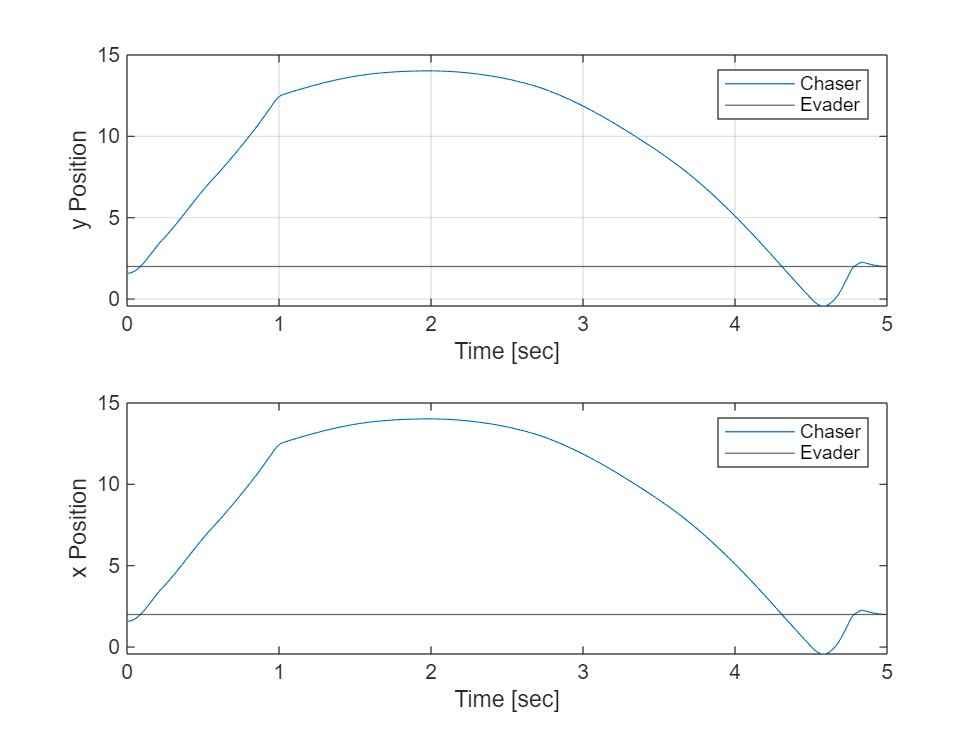

tspan = sol.x; 
y = sol.y; 

clf; 
hold on; 
grid on; 
subplot(2, 1, 1); 
plot(tspan, y(1, :)); 
yline(evaderPosition(1)); 
xlabel("Time [sec]"); 
ylabel("y Position"); 
legend("Chaser", "Evader"); 
hold off; 
hold on; 
grid on; 
subplot(2, 1, 2); 
plot(tspan, y(2, :)); 
yline(evaderPosition(2)); 
xlabel("Time [sec]"); 
ylabel("x Position"); 
legend("Chaser", "Evader"); 
hold off; 

% Differential equations. 
function dydt = eqns(~, y, A, B, e, positionBounds, velocityBounds)
    % Equivalence threshold. 
    eps = 1E-3; 

    % Optimal control. 
    if y(7) > 0
        u_x = e(1); 
    else
        u_x = e(2); 
    end
    if y(8) > 0
        u_y = e(3); 
    else
        u_y = e(4); 
    end

    % Control constraints. 
    if abs(y(1) - positionBounds(1)) < eps
        u_x = e(2); 
    end
    if abs(y(1) - positionBounds(2)) < eps
        u_x = e(1); 
    end
    if abs(y(2) - positionBounds(3)) < eps
        u_y = e(4); 
    end
    if abs(y(2) - positionBounds(4)) < eps
        u_y = e(3); 
    end

    % Control vector assembly. 
    u = [u_x; u_y]; 

    % Position and velocity Constraints. 
    C_p = [1 0 0 0; 1 0 0 0; 0 1 0 0; 0 1 0 0]; 
    C_v = [0 0 1 0; 0 0 1 0; 0 0 0 1; 0 0 0 1]; 
    s_p = [ ...
        -y(1) + positionBounds(1); ...
        y(1) - positionBounds(2); ...
        -y(2) + positionBounds(3); ...
        y(2) - positionBounds(4)];
    s_v = [ ...
        -y(3) + velocityBounds(1); ...
        y(3) - velocityBounds(2); ...
        -y(4) + velocityBounds(3); ...
        y(4) - velocityBounds(4)]; 
    mu_p = max(0, s_p/eps); 
    mu_v = max(0, s_v/eps); 

    % Return value. 
    dydt = [ ...
        A*y(1:4)+B*u; ...
        -A.'*y(5:8) - C_p.'*mu_p - C_v.'*mu_v]; 
    % dydt = [ ...
    %     A*y(1:4)+B*u; ...
    %     -A.'*y(5:8)]; 
end

% Boundary conditions. 
function retval = boundaryConditions(y_a, y_b, initialStates, evaderPosition)
    % Zero final velocity. 
    retval = [ ...
        y_a(1) - initialStates(1); ...
        y_a(2) - initialStates(2); ...
        y_a(3) - initialStates(3); ...
        y_a(4) - initialStates(4); ...
        y_b(3); ...
        y_b(4); ...
        y_b(5) - 2*y_b(1) + 2*evaderPosition(1); ...
        y_b(6) - 2*y_b(2) + 2*evaderPosition(2)]; 

    % % Free final velocity. 
    % retval = [ ...
    %     y_a(1) - initialStates(1); ...
    %     y_a(2) - initialStates(2); ...
    %     y_a(3) - initialStates(3); ...
    %     y_a(4) - initialStates(4); ...
    %     y_b(5) - 2*y_b(1) + 2*evaderPosition(1); ...
    %     y_b(6) - 2*y_b(2) + 2*evaderPosition(2); ...
    %     y_b(7); ...
    %     y_b(8)]; 
end